## Import BIDS dataset

**Run 'eeglab' from the folder containing the eeglab codes. This will add all the relevant EEGLAB functions and directories to path.**

eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "bids-matlab-tools" v6.1 (see >> help eegplugin_bids)
EEGLAB: adding "bids-validator" v1.1 (see >> help eegplugin_bidsvalidator)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


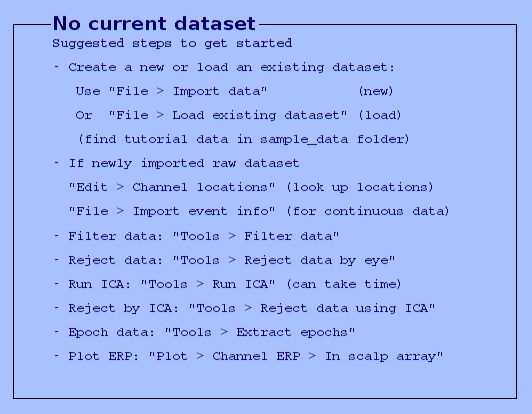

You are using the latest version of EEGLAB.


eeglab

**Steps:**

Select the BIDS folder to work on

BIDS_path = uigetdir(pwd,'Select BIDS dataset folder')

BIDS_path = '/home/user1/Documents/Manisha/eeglab-develop-2022/eeglab/BIDS/ds003969'

Add the folder and subfolders to path. Make the selected BIDS folder to current directory.

addpath(genpath(BIDS_path))

current_path = pwd;
if strcmp(current_path,BIDS_path)==0
    disp('Changing current directory to BIDS dataset folder')
    cd(BIDS_path)
end
[~,dataset_name,~] = fileparts(BIDS_path) 

dataset_name = 'ds003969'

The function pop_importbids() imports a BIDS format folder structure into an EEGLAB study. 

If 'bidsevent' is 'on' then events will be imported from the BIDS .tsv event file and events in the raw binary EEG files will be ignored. Similarly 'bidschanloc', 'on' will import channel locations from BIDS .tsv file and ignore any locations in raw EEG files. The 'studyName' field lets you specify the name of the newly created STUDY.

[STUDY, ALLEEG, opt] = pop_importbids(BIDS_path,'bidsevent','off','bidschanloc','off','studyName',dataset_name);

Importing file: /home/user1/Documents/Manisha/eeglab-develop-2022/eeglab/BIDS/ds003969/sub-001/eeg/sub-001_task-med1breath_eeg.bdf
Reading data in BDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Importing data events...
eeg_checkset note: creating the original event table (EEG.urevent)
readlocs(): 'elc' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240 250 260 270 280 290 300 310 320 330 340 350 360 370 380 390 400 410 420 430 440 450 460 470 480 490 500 510 520 530 540 550 560 570 580 590 600 610 620 630 640 650 660 670 680 690 700 702
Channel lookup: no location for EXG1,EXG2,EXG3,EXG4,EXG5,EXG6,EXG7,EXG8,GSR1,GSR2,Erg1,Erg2,Resp,Plet,Temp
Send us standard location for your channels at eeglab@sccn.ucsd.edu
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs
Saving dataset...
Importing file: /home

## BIDS_DL plugin

pop_bids_dl(STUDY, ALLEEG) % for ds003969

CURRENTSET = 6

No events file detected. Regular 2s epochs will be generated
The input dataset will be split into 302 epochs of 2 s
Inserting 302 type 'X' events: .......................................40
.......................................80..............................
.........120.......................................160....................
...................200.......................................240..........
.............................280......................
Sorting the event table.
Splitting the data into 302 2.00-s epochs
pop_epoch():302 epochs selected
Epoching...
pop_epoch():302 epochs generated
pop_epoch(): checking epochs for data discontinuity


eeg_dir = 'mat_files/sub-002/eeg'

eeg_uniformepochinfo: found empty values for field 'edftype' for 603 epochs
                      filling with values of other events in the same epochs
                      note: epochs not uniform (should be multiple of 302 epochs)
Analyzing and transferring files to the workers ...done.


## Training with 12x12 interpolated data

## Create the datastore

train_imds = imageDatastore('/home/user1/Documents/Manisha/eeglab-develop-2022/eeglab/BIDS/ds003969/mat_files', 'FileExtensions','.mat','IncludeSubfolders',true);

## Custom reader function

load_sample = @(x) x.Z_12; 
readfun = @(x) load_sample(load(x));


train_imds.ReadFcn = readfun;

## Preview the first sample of the datastore

sample = preview(train_imds);
fprintf('Sample size = %d, %d, %d\n', size(sample));

Sample size = 12, 12, 2048


## Assign labels

train_label_info = readtable('ds003969_Z12_labels_s3.csv');
train_label_info_sorted = sortrows(train_label_info,1);
label_col =train_label_info_sorted.Var5; % sex of the subject has header Var5 
train_imds.Labels = categorical(label_col);

Note: the labels here have been sorted to match the order of Files (works for Mac/Linux and AWS - need to check for Windows).

## Define the network layers to be trained

channels = [12, 12]; %range of channels 
num_samples = 2048; %num of samples
image_size = [channels(1) channels(2) 2048]; 

num_labels = size(unique(train_imds.Labels),1);

layers = [
    imageInputLayer(image_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## Training the network

Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',40, ...
    'MiniBatchSize',40);
    

Train the network

eeg_net = trainNetwork(train_imds,layers,options);

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       52.50% |       7.5726 |          0.0005 |
|      40 |          40 |       00:00:08 |      100.00% |  -0.0000e+00 |          0.0005 |
|========================================================================================|
Training finished: Max epochs completed.
